exist(fullfile(pwd,'.git'), 'dir')

ans = 0

git init

Unrecognized function or variable 'git'.

git add .
git commit -m "Initial commit"
git remote add origin https://github.com/benjamintang358/Ribosome-ER-Code
git push -u origin main

Here is the code for the paper discussing the ER structure and Ribosome density

First, we will cover the single sheet vs single tube geometry

% Here we simulate the simple stuff, like one disk and one tube which has
% known capacitance
% All in CGS units, so centimeters
% Based on West paper, ribosomes have radius 5nm, tubules have radius 20nm
clear;
clc;

r = 5 * 10^(-9) * 10^2; % cm
R = 1* 10^(-6)* 10^2; % cm
N_max = R^2 / r^2;
N = linspace(1,N_max,round(N_max)/10);
L = 2 * R;
W = 2 * R;
a = W / (2 * pi);
D = 1;
c_inf = 1;

C_disk = 2 * R / pi;
C_tube = L / (2 * log( 2 * L / a));

J_disk = 4 * pi * D * c_inf * C_disk; 
J_tube = 4 * pi * D * c_inf * C_tube; 

ratio_flux_disk_tube = J_disk / J_tube;
ratio_capacitance_disk_tube = C_disk / C_tube;

% Next we simulate the ribosomes on the disk

C_ribo_disk = N .* r .* R ./ (pi/2 .* N .* r + pi * R);
ratio_capacitance_ribo_disk = C_ribo_disk ./ C_disk;

total_area = pi * R^2; % Get um^2
ribosome_area = pi * r^2; 


% % Here are some plots for single sheet
% figure
% set(gcf,'Color','w','Position',[100 100 600 800])
% 
% t = tiledlayout(2,1, ...
%     'TileSpacing','loose', ...
%     'Padding','loose');
% 
% nexttile
% plot(N * ribosome_area ./ total_area, ratio_capacitance_ribo_disk,'LineWidth',1.5)
% title('Linear Scale','FontSize',12)
% xlabel('Fraction of Area Covered','FontSize',12)
% grid on
% 
% nexttile
% plot(log10(N * ribosome_area ./ total_area), ratio_capacitance_ribo_disk,'LineWidth',1.5)
% xlabel('Log_{10} Fraction of Area Covered','FontSize',12)
% title('Log_{10} Scale','FontSize',12)
% grid on
% 
% ylabel(t,'Fraction of Total Capacitance','FontSize',12)
% 
% 
% set(gcf,'Color','w')
% set(findall(gcf,'Type','axes'),'FontSize',12)
% 
% 
% % After all plotting is done
% annotation('textbox',[0.08 0.93 0.05 0.05], ...
%            'String','(a)', ...
%            'LineStyle','none', ...
%            'FontWeight','bold', ...
%            'FontSize',12);
% 
% annotation('textbox',[0.08 0.47 0.05 0.05], ...
%            'String','(b)', ...
%            'LineStyle','none', ...
%            'FontWeight','bold', ...
%            'FontSize',12);


Here we work on the double sheet geometry

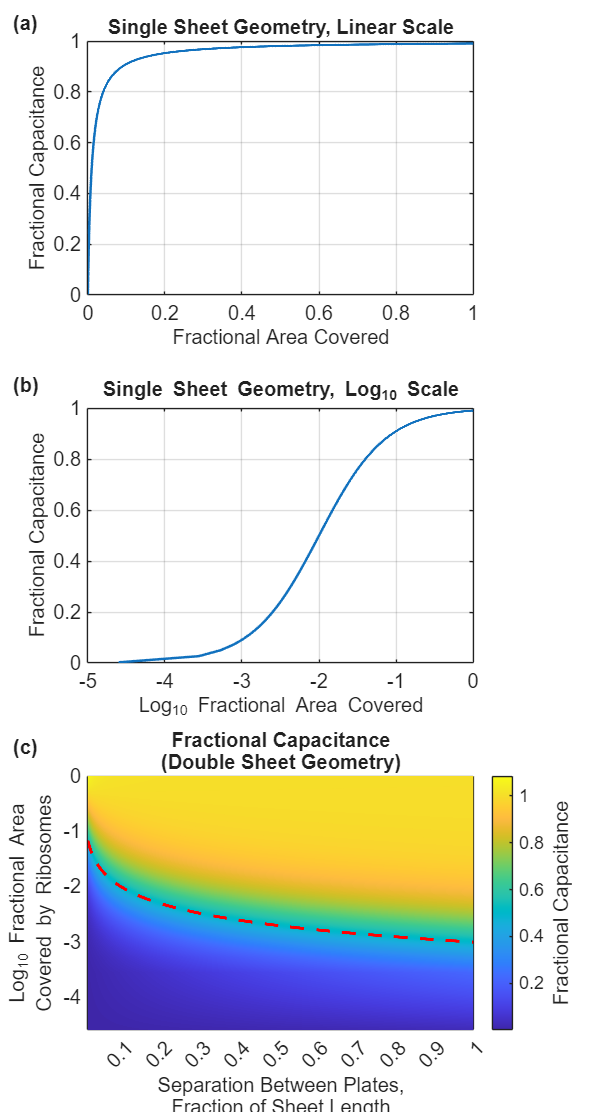

% Here is graphing the ratio of capacitance of disks vs whole for parallel
% sheets because it already is a function of N and spacing d
% Parameters
r = 5 * 10^(-9) * 10^2; % cm
R = 1* 10^(-6)* 10^2; % cm
N_max = R^2/r^2;
d = linspace(5*r,2*R,round(N_max)/10);          % separation between sheets [m]

% Number of disks N
%N_correction = 8 * d * R / (pi * r^2);
N = linspace(1, N_max, round(N_max)/10);

% Define variables
C_parallel = zeros(length(N),length(d));
C_ribSheet = zeros(length(N),length(d));

% Constants
% Intersheet interaction coefficient
beta = pi/2;
gamma = zeros(length(d));


for i = 1:length(N)
    for j = 1:length(d)
        % Opposite-sheet interaction coefficient
        gamma(j) = d(j) .* (8 .* d(j) - pi * (R + 2*r)) ./ (2 * R^2);

        C_parallel(i,j) = R^2 / (4 * d(j));
        C_ribSheet(i,j) = d(j) .* N(i).*2 .* r .* R ./ (beta .* d(j) .* N(i).*2 .* r + d(j) .* pi .* R + N(i).*2 .* r .* R .* gamma(j));
    end
end

% Parallel plate capacitance
%C_parallel = R^2 ./ (4 .* d);

% Ribosome sheet capacitance
% We times 2 for N since 2 N are used, one per sheet
%C_ribSheet = d .* N.*2 .* r .* R ./ (beta .* d .* N.*2 .* r + d .* pi .* R + N.*2 .* r .* R .* gamma);

% Fraction of parallel plate
C_frac = C_ribSheet ./ C_parallel;


% Here is a better plot

total_area = pi * R^2; % Get um^2
ribosome_area = pi * r^2; 

%% --- Figure 1: Fractional Capacitance and Coverage for Single and Double Sheet ---

figure
set(gcf,'Color','w','Position',[100 100 800 1500])   % tall figure for 3 panels

% --- Tiled layout ---
t = tiledlayout(3,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');

%% --- Panel A ---
ax1 = nexttile;
plot(N * ribosome_area ./ total_area, ratio_capacitance_ribo_disk, 'LineWidth',1.5)
title({'Single Sheet Geometry, Linear Scale'},'FontSize',12)
xlabel('Fractional Area Covered','FontSize',12)
ylabel('Fractional Capacitance','FontSize',12)
grid on

% --- X-axis: separation fraction 0-1 in steps of 0.1 ---
xticks = 0:0.2:1;
set(gca,'YTick', xticks)

% % --- Y-axis: log10 fractional area from min to max in steps of 0.1 log units ---
% ymin = floor(min(log10(N.*ribosome_area./total_area)));
% ymax = ceil(max(log10(N.*ribosome_area./total_area)));
% yticks = ymin:1:ymax;
% set(gca,'XTick', yticks)

%% --- Panel B ---
ax2 = nexttile;
plot(log10(N * ribosome_area ./ total_area), ratio_capacitance_ribo_disk, 'LineWidth',1.5)
title({'Single Sheet Geometry, Log_{10} Scale'},'FontSize',12)
xlabel('Log_{10} Fractional Area Covered','FontSize',12)
ylabel('Fractional Capacitance','FontSize',12)
grid on

% --- X-axis: separation fraction 0-1 in steps of 0.1 ---
xticks = 0:0.2:1;
set(gca,'YTick', xticks)

% --- Y-axis: log10 fractional area from min to max in steps of 0.1 log units ---
ymin = floor(min(log10(N.*ribosome_area./total_area)));
ymax = ceil(max(log10(N.*ribosome_area./total_area)));
yticks = ymin:1:ymax;
set(gca,'XTick', yticks)

%% --- Panel C ---
%% --- Panel C with ticks and 50% contour ---
ax3 = nexttile;
h = pcolor(d./(2*R), log10(N.*ribosome_area./total_area), C_frac);
set(h,'EdgeColor','none')
shading interp
colormap(parula(256))
set(gca,'YDir','normal')
axis tight

% --- X-axis: separation fraction 0-1 in steps of 0.1 ---
xticks = 0:0.1:1;
set(gca,'XTick', xticks)

% --- Y-axis: log10 fractional area from min to max in steps of 0.1 log units ---
ymin = floor(min(log10(N.*ribosome_area./total_area)));
ymax = ceil(max(log10(N.*ribosome_area./total_area)));
yticks = ymin:1:ymax;
set(gca,'YTick', yticks)

xlabel({'Separation Between Plates,'; 'Fraction of Sheet Length'},'FontSize',12)
ylabel({'Log_{10} Fractional Area'; 'Covered by Ribosomes'},'FontSize',12)
title({'Fractional Capacitance'; '(Double Sheet Geometry)'},'FontSize',12)

% --- Colorbar ---
cb = colorbar(ax3, 'eastoutside');
cb.Label.String = 'Fractional Capacitance';
cb.Label.FontSize = 12;

% --- Add contour line for 50% fractional capacitance ---
hold on
[C50,h50] = contour(d./(2*R), log10(N.*ribosome_area./total_area), C_frac, [0.5 0.5], ...
                    'r--', 'LineWidth',2);  % black line
hold off

%% --- Uniform typography ---
set(findall(gcf,'Type','axes'),'FontSize',12)
set(findall(gcf,'Type','text'),'FontSize',12)

%% --- Panel labels relative to axes ---
label_offset_x = -0.08; % slightly left of axes
label_offset_y = -0.02;  % slightly above top

% Panel A
annotation('textbox', 'Units','normalized', ...
    'Position',[ax1.Position(1)+label_offset_x, ax1.Position(2)+ax1.Position(4)+label_offset_y, 0.05, 0.05], ...
    'String','(a)','LineStyle','none','FontWeight','bold','FontSize',12);

% Panel B
annotation('textbox', 'Units','normalized', ...
    'Position',[ax2.Position(1)+label_offset_x, ax2.Position(2)+ax2.Position(4)+label_offset_y, 0.05, 0.05], ...
    'String','(b)','LineStyle','none','FontWeight','bold','FontSize',12);

% Panel C
annotation('textbox', 'Units','normalized', ...
    'Position',[ax3.Position(1)+label_offset_x, ax3.Position(2)+ax3.Position(4)+label_offset_y, 0.05, 0.05], ...
    'String','(c)','LineStyle','none','FontWeight','bold','FontSize',12);

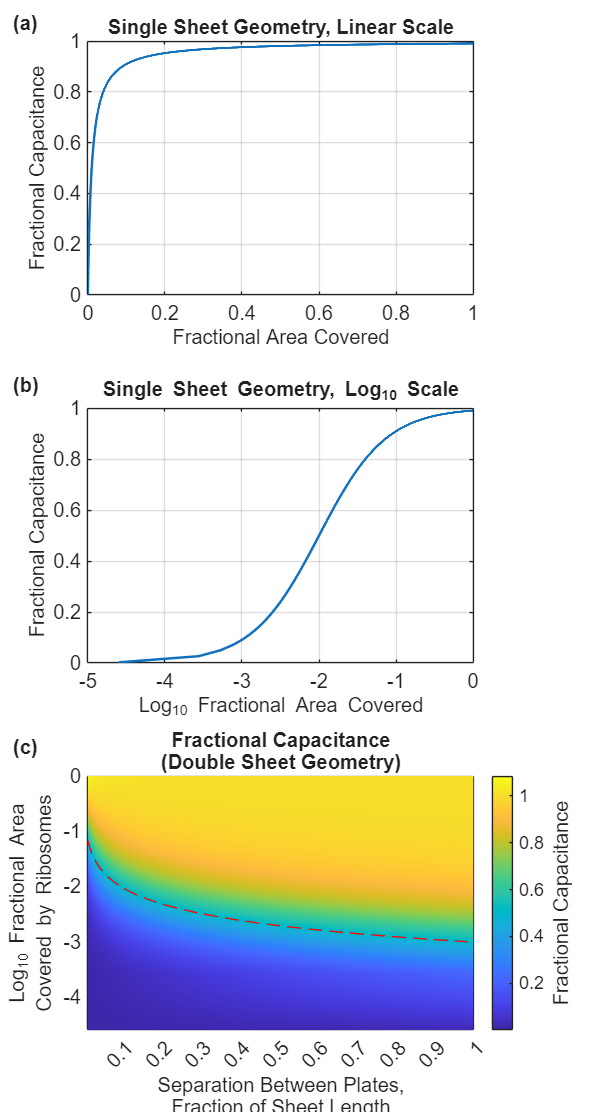


%% --- Optional: export PDF for PRL ---
exportgraphics(gcf,'figure1v1.pdf','ContentType','image','Resolution',300)

This section now finds the difference in relative capacitances between the double sheet and single sheet geometries

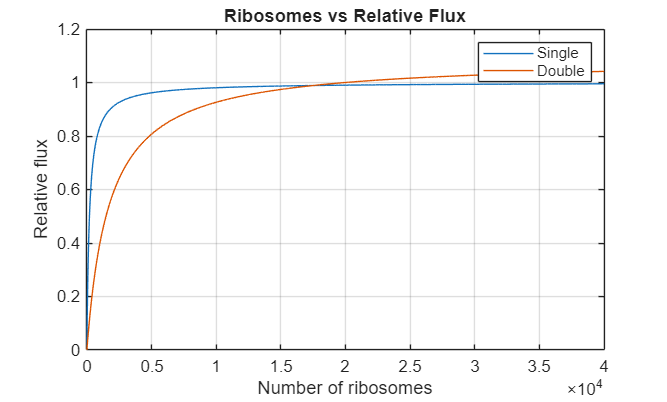

% So the actual thing that is important is the ratio of capacitances, and I
% think there will be a d such that the double sheet is more efficient than
% the single sheet

% Parameters
r = 5 * 10^(-9) * 10^2; % cm
R = 1* 10^(-6)* 10^2; % cm
N_max = R^2 / r^2;
d = linspace(5*r,2*R, round(N_max/10));          % separation between sheets [m]

% Number of disks N
%N_correction = 8 * d * R / (pi * r^2);

N = linspace(1, N_max, round(N_max/10));


% Define variables
C_parallel = zeros(length(N),length(d));
C_ribSheet = zeros(length(N),length(d));

% Constants
% Intersheet interaction coefficient
beta = pi/2;
gamma = zeros(length(d));


for i = 1:length(N)
    for j = 1:length(d)
        % Opposite-sheet interaction coefficient
        gamma(j) = d(j) .* (8 .* d(j) - pi * (R + 2*r)) ./ (2 * R^2);

        C_parallel(i,j) = R^2 / (4 * d(j));
        C_ribSheet(i,j) = d(j) .* N(i).*2 .* r .* R ./ (beta .* d(j) .* N(i).*2 .* r + d(j) .* pi .* R + N(i).*2 .* r .* R .* gamma(j));
    end
end

% Fraction of parallel plate
%C_double_max = max(C_double_unnom,[],"all");
C_double = min(2, C_ribSheet ./ (C_parallel) );



% Next we simulate the ribosomes on the disk
%C_single_max = max(C_ribo_disk);
C_ribo_disk = 2.*N .* r .* R ./ (pi/2 .* 2.*N .* r + pi * R);
C_disk = 2 * R / pi;
C_single = C_ribo_disk ./ (C_disk);


figure()
plot(N, C_single, N, C_double(:,50))
xlabel("Number of ribosomes")
ylabel("Relative flux")
title("Ribosomes vs Relative Flux")
grid on
legend(["Single", "Double"])

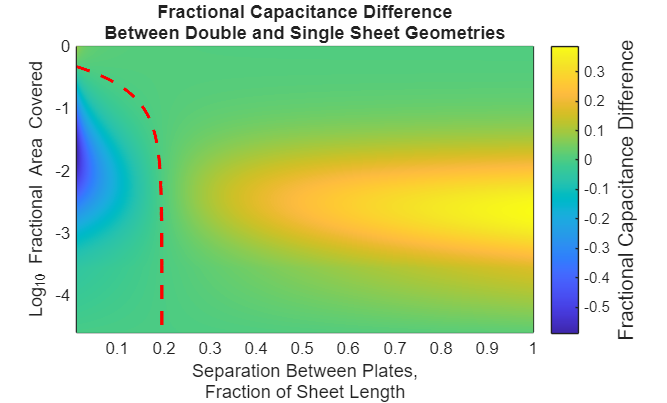



% Now we need to show that there is a critical distance where double sheets
% is more efficient than single

P_difference = zeros(length(N),length(d));

for i = 1:length(d)
    P_difference(:,i) = C_double(:,i) - C_single';
end




% This is figure 2
figure
h = pcolor(d./(2*R), log10(N.*ribosome_area./total_area), P_difference);
set(h,'EdgeColor','none')
shading interp
colormap(parula(256))
colorbar

set(gca,'YDir','normal')
axis tight

xlabel({'Separation Between Plates,';'Fraction of Sheet Length'})
ylabel('Log_{10} Fractional Area Covered')
title({'Fractional Capacitance Difference';'Between Double and Single Sheet Geometries'})

cb = colorbar;
cb.Label.String = 'Fractional Capacitance Difference';
cb.Label.FontSize = 12;

% --- Add contour line for 50% fractional capacitance ---
hold on
[C50,h50] = contour(d./(2*R), log10(N.*ribosome_area./total_area), P_difference, [0 0], ...
                    'r--', 'LineWidth',2);  % black line
hold off

% --- X-axis: separation fraction 0-1 in steps of 0.1 ---
xticks = 0:0.1:1;
set(gca,'XTick', xticks)
% --- Y-axis: log10 fractional area from min to max in steps of 0.1 log units ---
ymin = floor(min(log10(N.*ribosome_area./total_area)));
ymax = ceil(max(log10(N.*ribosome_area./total_area)));
yticks = ymin:1:ymax;
set(gca,'YTick', yticks)

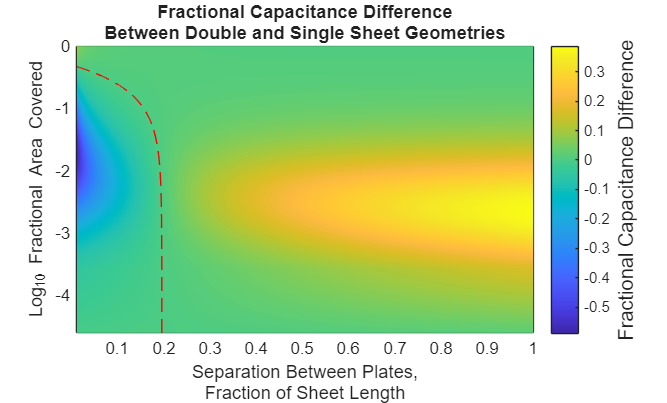

%% --- Optional: export PDF for PRL ---
exportgraphics(gcf,'figure2v1.pdf','ContentType','image','Resolution',300)

Skip for makign figures

%% --- Find zero crossing at d/(2R) = 0.05 ---

% Target separation
d_target = 0.025 * 2 * R;   % = 0.1 R

% Interpolate P_difference at fixed d
P_slice = interp1(d, P_difference.', d_target, 'linear').';

% Find first zero crossing
idx = find(P_slice(1:end-1).*P_slice(2:end) <= 0, 1);

% Linear interpolation to get N at zero crossing
N0 = interp1(P_slice(idx:idx+1), N(idx:idx+1), 0);

% Convert to log10 fractional area covered
frac_area_0 = N0 * r^2 / R^2;
log10_frac_area_0 = log10(frac_area_0);

% Display result
fprintf('Zero crossing at log10 fractional area ≈ %.3f\n', ...
        log10_frac_area_0);

%% --- Optional sanity check plot ---

figure
plot(log10(N.*r^2./R^2), P_slice, 'LineWidth',1.5)
hold on
yline(0,'k--')
xline(log10_frac_area_0,'r--','LineWidth',1.5)
hold off

xlabel('Log_{10} Fractional Area Covered')
ylabel('P_{double} - P_{single}')
title('Zero Crossing at d/(2R) = 0.05')
grid on


Here is the code that works on the tubes, and then the tubular matrix

Skip this for making figures

% Now we work on tubes
% Parameters
r = 5 * 10^(-9) * 10^2; % cm
R = 1* 10^(-6)* 10^2; % cm
a = R / (pi);  % Radius of tube [m]
N_max = R^2 / r^2;
d = linspace(5*r,2*R,round(N_max/50));          % separation between sheets [m]
L = R;

% Number of disks N
%N_correction = 8 * d * R / (pi * r^2);

N = linspace(1, N_max, round(N_max/50));
length(N);


% Define variables
C_tube = N;
C_ribTube = N;

% Constants
% Intersheet interaction coefficient
lambda = 1 - pi * r / ( 8 * a * log(2 * L / a) );


for i = 1:length(N)
    C_tube(i) = L / ( 2 * log(2 * L / a) );
    C_ribTube(i) = 2 * L .* N(i) .* r ./ ( L * pi + 4 .* N(i) .* r * lambda * log(2 * L / a) );
end

C_ratio_tube = C_ribTube ./ C_tube;

figure()
plot(N,C_ratio_tube,N, C_single, N, C_double(:,50))
xlabel("Number of ribosomes")
ylabel("Ratio of Tube flux")
title("Ribosomes vs Tube capacitance")
grid on
legend(["Tube", "Single sheet", "Double sheet"])



% So it seems the tube saturates faster, so worth comparing the tube to
% single sheet as a function of N

C_diff_tube_sheet = C_ribTube - C_ribo_disk;

figure()
plot(N,C_diff_tube_sheet)
xlabel("Number of ribosomes")
ylabel("Difference in Capacitance")
title("Ribosomes vs difference capacitance")
grid on
%legend(["Tube", "Single sheet", "Double sheet"])

Working on tube geometry now for figure 3

% Now let's explore the tube geometry as a function of N

% Parameters
r = 5 * 10^(-9) * 10^2; % cm
R = 1* 10^(-6)* 10^2; % cm
L = 2 * R;
a = L / (2 * pi);
N_max = 2 * a * L / r^2;
%a = linspace(5*r,2 * R, round(N_max/100));          % separation between sheets [m]


% Number of disks N
%N_correction = 8 * d * R / (pi * r^2);

N = linspace(1, N_max, round(N_max/10));
length(N);


% Define variables
C_tube = zeros(length(N), length(a));
C_ribTube = zeros(length(N), length(a));

% Constants
% Intersheet interaction coefficient
lambda = zeros(length(a));


for i = 1:length(N)
    for j = 1:length(a)
        lambda(j) = 1 - pi * r / ( 8 * a * log(2 * L / a) );
        C_tube(i,j) = L / ( 2 * log(2 * L / a) );
        C_ribTube(i,j) = 2 * L .* N(i) .* r ./ ( L * pi + 4 .* N(i) .* r * lambda(j) * log(2 * L / a) );
    end
end

C_ratio_tube = C_ribTube ./ C_tube;

total_area = pi * L * 2 * a; % Get um^2
ribosome_area = pi * r^2; 

% % Realized this is the right plot
% figure()
% plot(N, C_ratio_tube)
% xlabel('log_{10} Fractional Area Covered')
% ylabel('Fractional Capacitance')
% title('Tube Geometry')
% grid on
% 
% figure()
% plot(log10(N.*ribosome_area./total_area), C_ratio_tube)
% xlabel('log_{10} Fractional Area Covered')
% ylabel('Fractional Capacitance')
% title('Tube Geometry')
% grid on


% % This one looks good
% figure
% h = pcolor(a./(2*R), log10(N.*ribosome_area./total_area), C_ratio_tube);
% set(h,'EdgeColor','none')
% shading interp
% colormap(parula(256))
% colorbar
% 
% set(gca,'YDir','normal')
% axis tight
% 
% xlabel('Radius of Tube, Fraction of Plate Length')
% ylabel('Log_{10} Fractional Area Covered')
% title('Fractional Capacitance for Tube Geometry')
% 
% cb = colorbar;
% cb.Label.String = 'Fractional Capacitance';
% cb.Label.FontSize = 12;

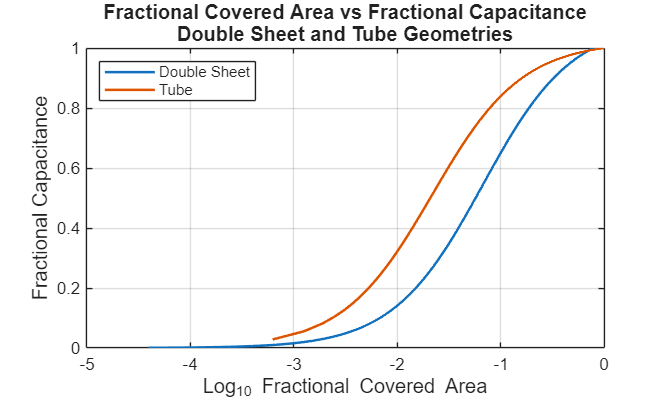

% Now let's push it to compare versus the ppc at the known distance

d_ppc = 50 * 10^(-9) * 10^2; 
a_tube = 20 * 10^(-9) * 10^2; 
l_tube = 1 * 10^(-6) * 10^2; 

r = 5 * 10^(-9) * 10^2; 
R = 1 * 10^(-6) * 10^2; 
L = 2 * R;
W = R;

N_max_ppc = L * W / (pi * r^2);
N_max_tube = l_tube * 2 * pi * a_tube / (pi * r^2);

N_ppc = linspace(1,N_max_ppc, N_max_ppc);
N_tube = linspace(1,N_max_tube, N_max_tube);

beta = pi/2;
gamma = d_ppc .* (8 .* d_ppc - pi * (R + 2*r)) ./ (2 * R^2);

C_ribSheet = zeros(1, length(N_ppc));
C_ppc = R^2 / (4 * d_ppc);

for i = 1:length(N_ppc)
    C_ribSheet(i) = d_ppc .* N_ppc(i).*2 .* r .* R ./ (beta .* d_ppc .* N_ppc(i).*2 .* r + d_ppc .* pi .* R + N_ppc(i).*2 .* r .* R .* gamma);
end

ratio_ppc = C_ribSheet ./ C_ppc;
total_area_ppc = L * W;


lambda = 1 - pi * r / ( 8 * a_tube * log(2 * l_tube / a_tube) );
C_tube = l_tube / ( 2 * log(2 * l_tube / a_tube) );
C_ribTube = zeros(1, length(N_tube));

for i = 1:length(N_tube)
    C_ribTube(i) = 2 * l_tube .* N_tube(i) .* r ./ ( l_tube * pi + 4 .* N_tube(i) .* r * lambda * log(2 * l_tube / a_tube) );
end

ratio_tube = C_ribTube ./ C_tube;
total_area_tube = l_tube * 2 * pi * a_tube;

figure()
plot(log10(N_ppc .* pi .* r^2 ./ total_area_ppc), ratio_ppc, log10(N_tube .* pi .* r^2 ./ total_area_tube), ratio_tube,'LineWidth',1.5)
xlabel("Log_{10} Fractional Covered Area",'FontSize',12)
ylabel("Fractional Capacitance",'FontSize',12)
grid on
legend(["Double Sheet","Tube"], 'Location', "northwest")
title({'Fractional Covered Area vs Fractional Capacitance';'Double Sheet and Tube Geometries'},'FontSize',12)
xlim([-5,0])
ylim([0,1])

% This tells me what ribo/um^2 the geometries have at some log 10
% fractional covered area
filling_ppc = 10^(-1.24) * N_max_ppc / (total_area_ppc * 10^(8));
filling_tube = 10^(-1.67) * N_max_tube / (total_area_tube * 10^(8));

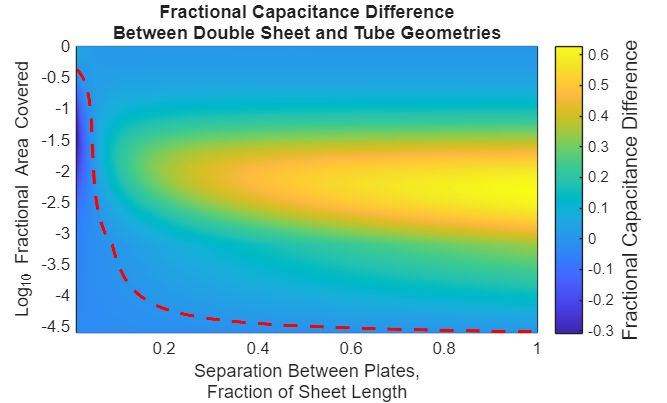

% Now let's make the surface plot similar to what we did for single vs
% double sheets but with tube as the constant

r = 5 * 10^(-9) * 10^2; % cm
R = 1* 10^(-6)* 10^2; % cm
N_max = R^2/r^2;
d = linspace(5*r,2*R,round(N_max)/10);          % separation between sheets [m]

% Number of disks N
%N_correction = 8 * d * R / (pi * r^2);
N = linspace(1, N_max, N_max_tube);

% Define variables
C_parallel = zeros(length(N),length(d));
C_ribSheet = zeros(length(N),length(d));

% Constants
% Intersheet interaction coefficient
beta = pi/2;
gamma = zeros(length(d));


for i = 1:length(N)
    for j = 1:length(d)
        % Opposite-sheet interaction coefficient
        gamma(j) = d(j) .* (8 .* d(j) - pi * (R + 2*r)) ./ (2 * R^2);

        C_parallel(i,j) = R^2 / (4 * d(j));
        C_ribSheet(i,j) = d(j) .* N(i).*2 .* r .* R ./ (beta .* d(j) .* N(i).*2 .* r + d(j) .* pi .* R + N(i).*2 .* r .* R .* gamma(j));
    end
end

% Fraction of parallel plate
C_frac = C_ribSheet ./ C_parallel;


% Now subtract
C_diff_ppc_tube = C_frac;
total_area = pi * R^2; % Get um^2
ribosome_area = pi * r^2; 

for i = 1:length(d)
    C_diff_ppc_tube(:,i) = C_frac(:,i) - ratio_tube';
end

% Now plot
figure
h = pcolor(d./(2*R), log10(N.*ribosome_area./total_area), C_diff_ppc_tube);
set(h,'EdgeColor','none')
shading interp
colormap(parula(256))
colorbar

set(gca,'YDir','normal')
axis tight

xlabel({'Separation Between Plates,';'Fraction of Sheet Length'})
ylabel('Log_{10} Fractional Area Covered')
title({'Fractional Capacitance Difference';'Between Double Sheet and Tube Geometries'})

cb = colorbar;
cb.Label.String = 'Fractional Capacitance Difference';
cb.Label.FontSize = 12;

% --- Add contour line for 50% fractional capacitance ---
hold on
[C50,h50] = contour(d./(2*R), log10(N.*ribosome_area./total_area), C_diff_ppc_tube, [0 0], ...
                    'r--', 'LineWidth',2);  % black line
hold off

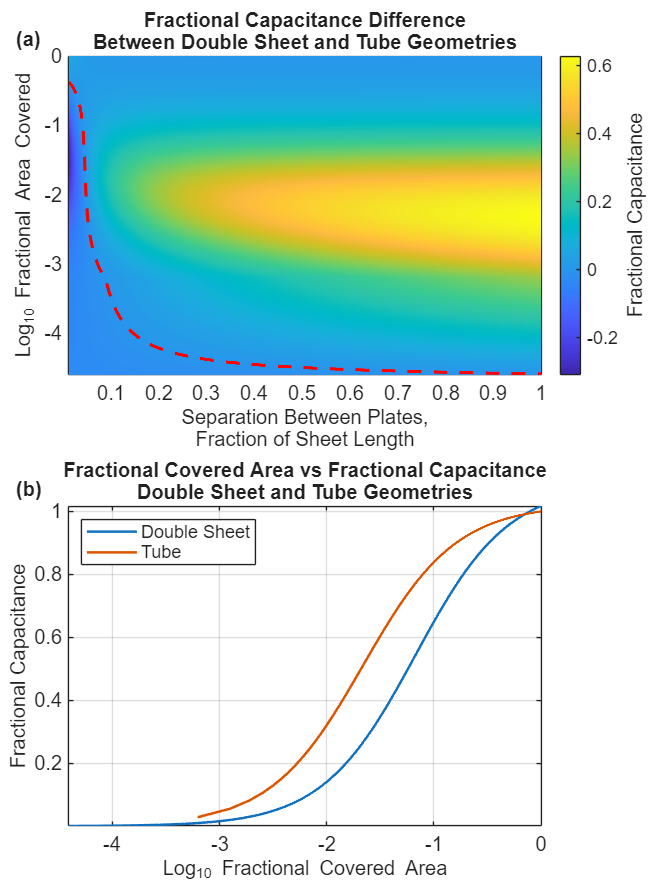

%% --- Figure 3: Fractional Capacitance and Coverage for Tubes ---

figure
set(gcf,'Color','w','Position',[100 100 600 800])   % tall figure for 3 panels

% --- Tiled layout ---
t = tiledlayout(2,1, ...
    'TileSpacing','compact', ...
    'Padding','compact');

%% --- Panel A ---
ax1 = nexttile;
h = pcolor(d./(2*R), log10(N.*ribosome_area./total_area), C_diff_ppc_tube);
set(h,'EdgeColor','none')
shading interp
colormap(parula(256))
colorbar

set(gca,'YDir','normal')
axis tight

xlabel({'Separation Between Plates,';'Fraction of Sheet Length'},'FontSize',12)
ylabel('Log_{10} Fractional Area Covered','FontSize',12)
title({'Fractional Capacitance Difference';'Between Double Sheet and Tube Geometries'},'FontSize',12)

cb = colorbar;
cb.Label.String = 'Fractional Capacitance Difference';
cb.Label.FontSize = 12;

% --- Add contour line for 50% fractional capacitance ---
hold on
[C50,h50] = contour(d./(2*R), log10(N.*ribosome_area./total_area), C_diff_ppc_tube, [0 0], ...
                    'r--', 'LineWidth',2);  % black line
hold off

% --- X-axis: separation fraction 0-1 in steps of 0.1 ---
xticks = 0:0.1:1;
set(gca,'XTick', xticks)
% --- Y-axis: log10 fractional area from min to max in steps of 0.1 log units ---
ymin = floor(min(log10(N.*ribosome_area./total_area)));
ymax = ceil(max(log10(N.*ribosome_area./total_area)));
yticks = ymin:1:ymax;
set(gca,'YTick', yticks)


%% --- Panel B ---
ax2 = nexttile;
plot(log10(N_ppc .* pi .* r^2 ./ total_area_ppc), ratio_ppc, log10(N_tube .* pi .* r^2 ./ total_area_tube), ratio_tube,'LineWidth',1.5)
xlabel("Log_{10} Fractional Covered Area",'FontSize',12)
ylabel("Fractional Capacitance",'FontSize',12)
legend(["Double Sheet","Tube"], 'Location', "northwest")
title({'Fractional Covered Area vs Fractional Capacitance';'Double Sheet and Tube Geometries'},'FontSize',12)
%xlim([-5,0])
ylim([0,1])

set(gca,'YDir','normal')
axis tight
grid on

% --- X-axis: separation fraction 0-1 in steps of 0.1 ---
xticks = 0:0.2:1;
set(gca,'YTick', xticks)

% cb = colorbar;
% cb.Label.String = 'Fractional Capacitance';
% cb.Label.FontSize = 12;

% --- Colorbar attached ONLY to last tile ---
cb = colorbar(ax1, 'eastoutside');
cb.Label.String = 'Fractional Capacitance';
cb.Label.FontSize = 12;



%% --- Uniform typography ---
set(findall(gcf,'Type','axes'),'FontSize',12)
set(findall(gcf,'Type','text'),'FontSize',12)

%% --- Panel labels relative to axes ---
label_offset_x = -0.08; % slightly left of axes
label_offset_y = -0.02;  % slightly above top


% Panel A
annotation('textbox', 'Units','normalized', ...
    'Position',[ax1.Position(1)+label_offset_x, ax1.Position(2)+ax1.Position(4)+label_offset_y, 0.05, 0.05], ...
    'String','(a)','LineStyle','none','FontWeight','bold','FontSize',12);

% Panel B
annotation('textbox', 'Units','normalized', ...
    'Position',[ax2.Position(1)+label_offset_x, ax2.Position(2)+ax2.Position(4)+label_offset_y, 0.05, 0.05], ...
    'String','(b)','LineStyle','none','FontWeight','bold','FontSize',12);

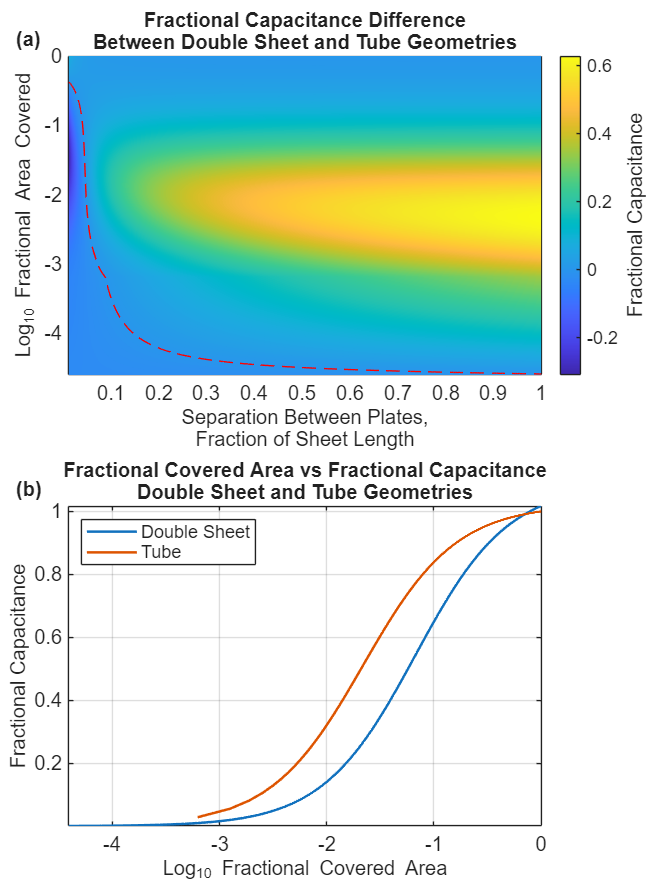

%% --- Optional: export PDF for PRL ---
exportgraphics(gcf,'figure3v1.pdf','ContentType','image','Resolution',300)

% Here we will simplify compare based on experimental data fixing
% parameters how much filling the tube needs to match the parallel plate
% geometry



% Now we look at the difference of tuluar matrix to double sheet

P_diff_matrix_sheet = C_ratio_full - C_double;

% Plot surface
figure()
surf(d,N, P_diff_matrix_sheet);              % Create a 3D surface plot
ylabel('Number of Ribosomes');
xlabel('Distance between sheets');
zlabel('P capture');
title("Surface Plot of Difference between tubular matrix and double sheet");


% This is Figure 4
figure
h = pcolor(d./(2*R), log10(N.*ribosome_area./total_area), P_diff_matrix_sheet);
set(h,'EdgeColor','none')
shading interp
colormap(parula(256))
colorbar

set(gca,'YDir','normal')
axis tight

xlabel('Separation Between Plates, Fraction of Sheet Length')
ylabel('Log_{10} Fractional Area Covered')
title({'Fractional Capacitance Difference Between';'Tubular Matrix and Double Sheet Geometries'})

cb = colorbar;
cb.Label.String = 'Fractional Capacitance Difference';
cb.Label.FontSize = 12;

%% --- Optional: export PDF for PRL ---
exportgraphics(gcf,'figure4.pdf','ContentType','image','Resolution',300)